#### **Question 4**

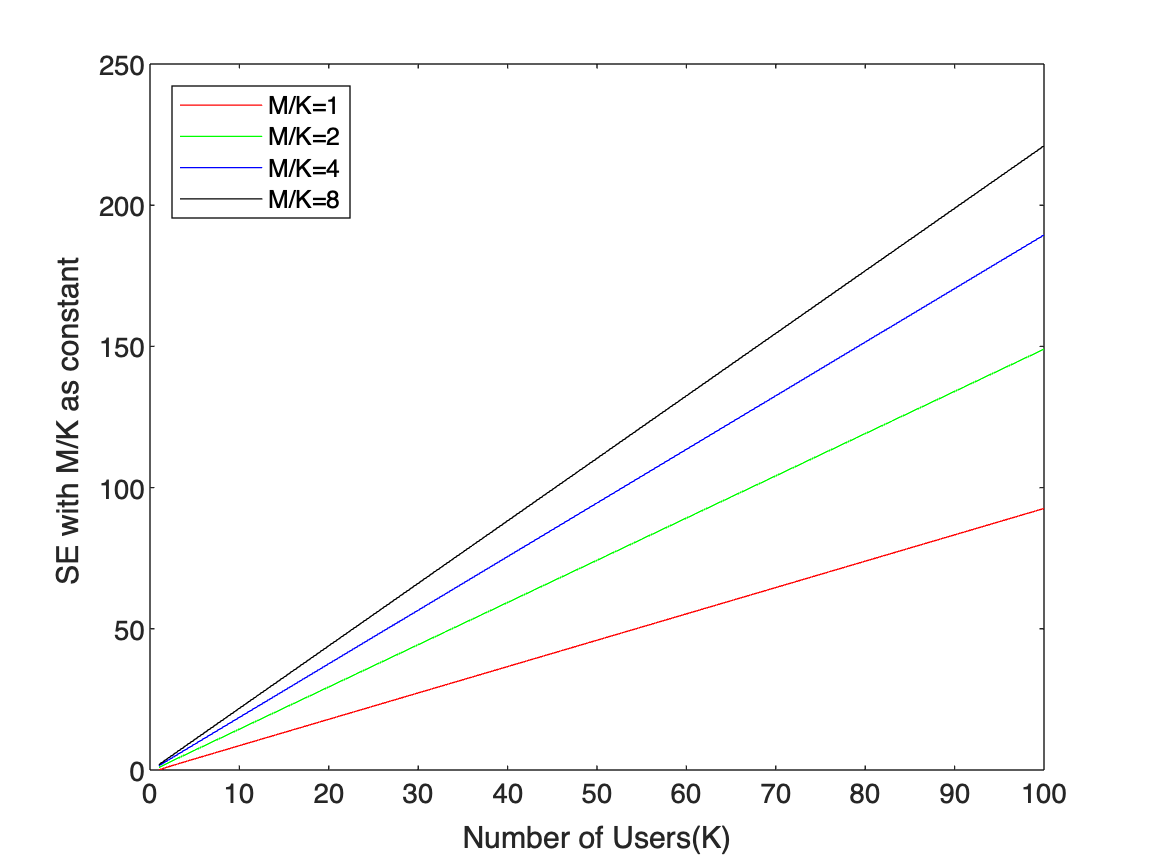

clear;
close all;
clc;

%initialising of constants.
users = 1:100;
beetabar = 0.1;
SNRo = 1;

%declaring a matrix for SE with zeros, so that it can be
% manipulated later.
%it has 4 rows corresponding to M/K = 1, M/K = 2, M/k = 4,
% M/K =8 respectively.
SE = zeros(4, length(users));

%calculating the SE.
for iter = 1:length(users)
    K = users(iter);
    %M/K =1;
    M = K;
    SE(1,iter) = K*log2(1 + (M-1)/((K-1) + K*beetabar + 1/SNRo));

    %M/K = 2.
    M = 2*K;
    SE(2,iter) = K*log2(1 + (M-1)/((K-1) + K*beetabar + 1/SNRo));

    %M/K = 4.
    M = 3*K;
    SE(3,iter) = K*log2(1 + (M-1)/((K-1) + K*beetabar + 1/SNRo));

    %M/K = 4.
    M = 4*K;
    SE(4,iter) = K*log2(1 + (M-1)/((K-1) + K*beetabar + 1/SNRo));

end

hold on; box on;
plot(users, SE(1,:), 'r-')
plot(users, SE(2,:), 'g-')
plot(users, SE(3,:), 'b-')
plot(users, SE(4,:), 'k-')

%labeling of axes.
xlabel('Number of Users(K)')
ylabel('SE with M/K as constant ')
%adding legends.
legend('M/K=1', 'M/K=2', 'M/K=4', 'M/K=8', 'Location','northwest')